%% EEG-Daten laden
data = load('eeg_data.mat');
time = data.time(:);   % Spaltenvektor erzwingen
cond1 = data.condition1;
cond2 = data.condition2;

% Prüfen der Dimensionen
disp(['Größe von cond1: ', mat2str(size(cond1))]);

Größe von cond1: [500 10]


disp(['Größe von cond2: ', mat2str(size(cond2))]);

Größe von cond2: [500 10]


disp(['Größe von time: ', mat2str(size(time))]);

Größe von time: [500 1]


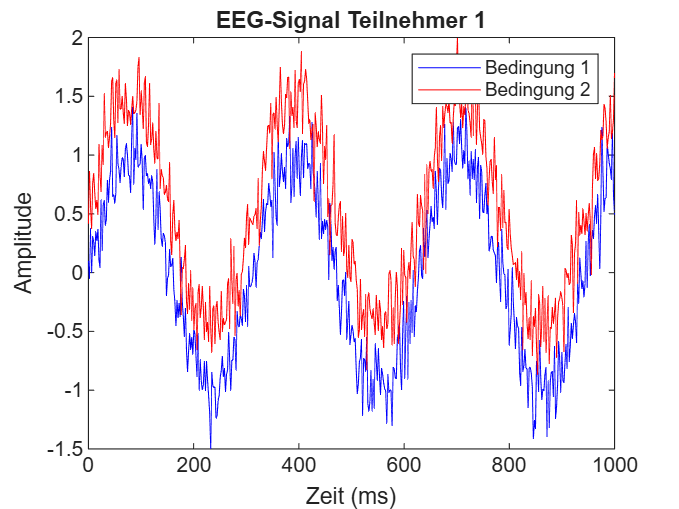


%% Plot für Teilnehmer 1
fig1 = figure;
plot(time, cond1(:,1), 'b'); hold on;
plot(time, cond2(:,1), 'r');
xlabel('Zeit (ms)'); ylabel('Amplitude');
legend('Bedingung 1','Bedingung 2');
title('EEG-Signal Teilnehmer 1');
saveas(fig1,'EEG_Teilnehmer1.png');  % Bild speichern

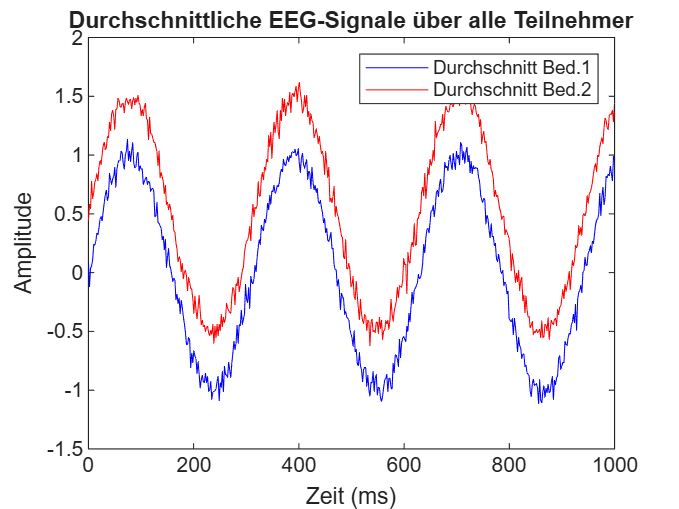


%% Vergleich: Durchschnitt über alle Teilnehmer
mean_cond1 = mean(cond1,2);
mean_cond2 = mean(cond2,2);

fig2 = figure;
plot(time, mean_cond1, 'b'); hold on;
plot(time, mean_cond2, 'r');
xlabel('Zeit (ms)'); ylabel('Amplitude');
legend('Durchschnitt Bed.1','Durchschnitt Bed.2');
title('Durchschnittliche EEG-Signale über alle Teilnehmer');
saveas(fig2,'EEG_Durchschnitt.png');  % Bild speichern

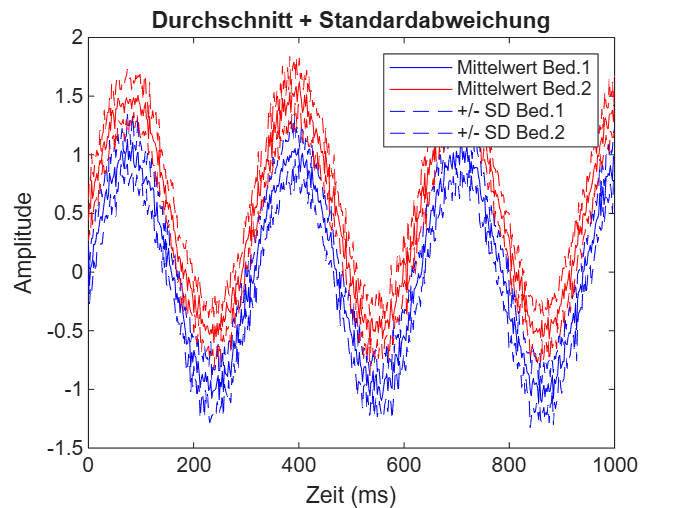


%% Standardabweichung über alle Teilnehmer
std_cond1 = std(cond1,0,2);
std_cond2 = std(cond2,0,2);

fig3 = figure;
plot(time, mean_cond1, 'b'); hold on;
plot(time, mean_cond2, 'r');
plot(time, mean_cond1 + std_cond1, '--b');
plot(time, mean_cond1 - std_cond1, '--b');
plot(time, mean_cond2 + std_cond2, '--r');
plot(time, mean_cond2 - std_cond2, '--r');
xlabel('Zeit (ms)'); ylabel('Amplitude');
legend('Mittelwert Bed.1','Mittelwert Bed.2','+/- SD Bed.1','+/- SD Bed.2');
title('Durchschnitt + Standardabweichung');
saveas(fig3,'EEG_Durchschnitt_SD.png');


%% T-Test zwischen den Bedingungen
[h,p] = ttest(cond1, cond2);

disp('T-Test Ergebnisse (erste 10 Zeitpunkte):');

T-Test Ergebnisse (erste 10 Zeitpunkte):


disp(p(1:10));

  1.0e-146 *

    0.0000    0.0000    0.0010    0.0118    0.0000    0.3354    0.0000    0.0000    0.0003    0.0000



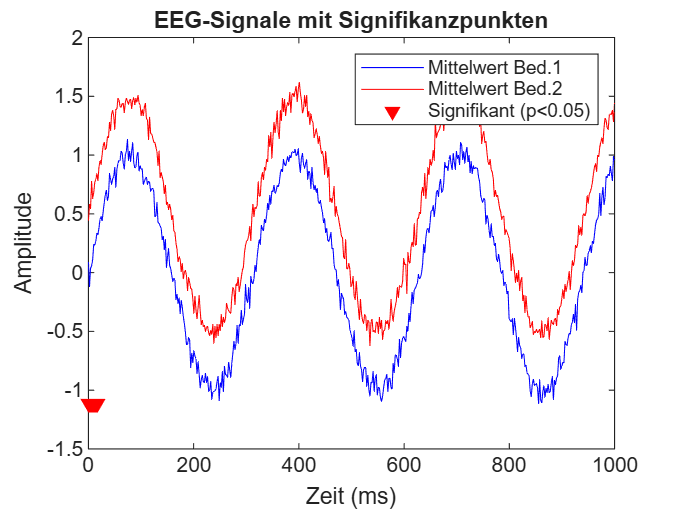


%% Signifikanz plotten
fig4 = figure;
plot(time, mean_cond1, 'b'); hold on;
plot(time, mean_cond2, 'r');
sig_idx = p < 0.05;
plot(time(sig_idx), min([mean_cond1; mean_cond2])*ones(sum(sig_idx),1), 'rv', 'MarkerFaceColor','r');
xlabel('Zeit (ms)'); ylabel('Amplitude');
legend('Mittelwert Bed.1','Mittelwert Bed.2','Signifikant (p<0.05)');
title('EEG-Signale mit Signifikanzpunkten');
saveas(fig4,'EEG_Signifikanz.png');


%% Ergebnisse als Textdatei speichern
fileID = fopen('EEG_Ergebnisse.txt','w');
fprintf(fileID,'EEG Datenanalyse Ergebnisse\n\n');

fprintf(fileID,'Mittelwerte Bedingung 1 (erste 10 Zeitpunkte):\n');
fprintf(fileID,'%f\n', mean_cond1(1:10));
fprintf(fileID,'\nMittelwerte Bedingung 2 (erste 10 Zeitpunkte):\n');
fprintf(fileID,'%f\n', mean_cond2(1:10));

fprintf(fileID,'\nStandardabweichung Bedingung 1 (erste 10 Zeitpunkte):\n');
fprintf(fileID,'%f\n', std_cond1(1:10));
fprintf(fileID,'\nStandardabweichung Bedingung 2 (erste 10 Zeitpunkte):\n');
fprintf(fileID,'%f\n', std_cond2(1:10));

fprintf(fileID,'\nT-Test p-Werte (erste 10 Zeitpunkte):\n');
fprintf(fileID,'%f\n', p(1:10));

fclose(fileID);
